clear all

data = importdata("Assignment_Data_SC42145_2022.mat");
FWT=data.FWT;
eye(2)

ans =      1     0
     0     1


G1 = FWT(1:2,1:2)

G1 =
 
  A = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s        -0.422       -0.2204             0       -0.2204             0
   z1dot (m/s)        0.02328      -0.01085         -0.04     -0.009574             0
   z1 (m)                   0             1             0             0             0
   z2dot (m/s)         0.1455      -0.05984             0       -0.1651        -10.82
   z2 (m)                   0             0             0             1             0
 
  B = 
                 Beta (deg)  tau_e (Nm)
   Omega (rad/s    -0.07988   -0.009564
   z1dot (m/s)    -0.006722           0
   z1 (m)                 0           0
   z2dot (m/s)     -0.04202           0
   z2 (m)                 0           0
 
  C = 
                 Omega (rad/s   z1dot (m/s)        z1 (m)   z2dot (m/s)        z2 (m)
   Omega (rad/s             1             0             0             0             0
   z (m)                    0           

s = tf('s')

s =
 
  s
 
Continuous-time transfer function.



G = G1.C*inv((s*eye(5)-G1.A))*G1.B

G =
 
  From input 1 to output...
                                                                                               
       -0.07988 s^14 - 0.09884 s^13 - 2.654 s^12 - 2.906 s^11 - 29.62 s^10 - 28.22 s^9         
                                                                                               
               - 114.1 s^8 - 91.37 s^7 - 33.67 s^6 - 11.32 s^5 - 2.878 s^4 - 0.4741 s^3        
                                                                                               
                                                          - 0.09734 s^2 - 0.006633 s - 0.001154
                                                                                               
   1:  ----------------------------------------------------------------------------------------
                                                                                               
       s^15 + 1.794 s^14 + 34 s^13 + 53.72 s^12 + 391.7 s^11 + 533.8 s^10 + 1611 s^9           
      

omega = [0, 0.6*pi];
    for i =1:length(omega)
        Gf=freqresp(G,omega(i));
        RGAw(:,:,i)=Gf.*inv(Gf).';
        RGAno(i)=sum(sum(abs(RGAw(:,:,i)-eye(2))));
        
    end
    RGA = frd(RGAw,omega)

RGA =

  From input 1 to:

    Frequency(rad/s)         output 1          output 2    
    ----------------         --------          --------    
         0.0000         -0.6554 + 0.0000i  1.6554 + 0.0000i
         1.8850         -0.0283 + 0.1398i  1.0283 - 0.1398i

  From input 2 to:

    Frequency(rad/s)        output 1           output 2    
    ----------------        --------           --------    
         0.0000         1.6554 + 0.0000i  -0.6554 + 0.0000i
         1.8850         1.0283 - 0.1398i  -0.0283 + 0.1398i
 
Continuous-time frequency response.



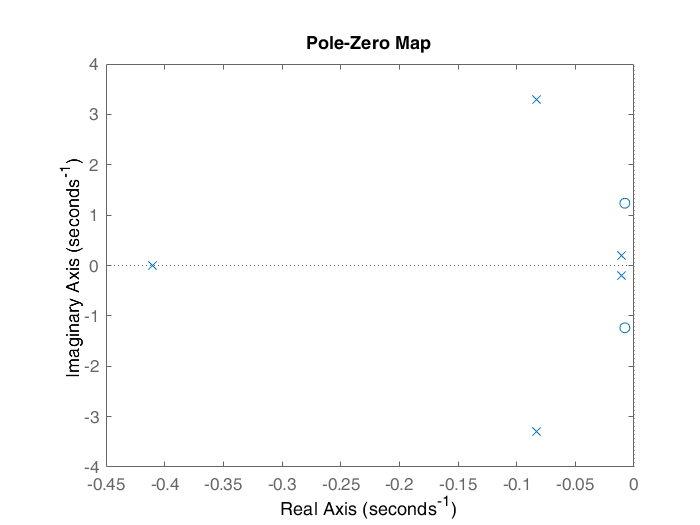

pzplot(FWT(1:2,1:2))

poles = pole(FWT(1:2,1:2))

poles =   -0.0832 + 3.2936i
  -0.0832 - 3.2936i
  -0.4104 + 0.0000i
  -0.0106 + 0.2022i
  -0.0106 - 0.2022i


zeros = zero(FWT(1:2,1:2))

zeros =   -0.0078 + 1.2358i
  -0.0078 - 1.2358i



G=tf(FWT(1:2,1:2))

G =
 
  From input "Beta (deg)" to output...
                   -0.07988 s^4 - 0.003315 s^3 - 0.8677 s^2 + 0.006493 s - 0.03458
   Omega (rad/s):  ---------------------------------------------------------------
                    s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
                  -0.04874 s^3 - 0.03481 s^2 - 0.07497 s - 0.052
   z (m):  ------------------------------------------------------------
           s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
  From input "tau_e (Nm)" to output...
                   -0.009564 s^4 - 0.001683 s^3 - 0.1039 s^2 - 0.001187 s - 0.00414
   Omega (rad/s):  ----------------------------------------------------------------
                     s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
                      -0.001614 s^2 - 2.522e-05 s - 0.002465
   z (m):  ------------------------------------------------------------
           s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827


wB1=0.3; % desired closed-loop bandwidth
wB2=0.2; % desired closed-loop bandwidth
A=1/1000; % desired disturbance attenuation inside bandwidth
M=3 ; % desired bound on hinfnorm(S)
Wp=[(s/M+wB1)/(s+wB1*A) 0; 0 wB2]; %
%Sensitivity weight
Wu22 =(5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6);
Wu=[0.01 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight


Wt =

     []




P11=[Wp;eye(2)];
P12=[Wp*G;Wu];
P21=eye(2);
P22=G;

P=[P11 P12; P21 P22]

P =
 
  From input 1 to output...
         s + 0.9
   1:  ------------
       3 s + 0.0009
 
   2:  0
 
   3:  1
 
   4:  0
 
   Omega (rad/s):  1
 
   z (m):  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2
 
   3:  0
 
   4:  1
 
   Omega (rad/s):  0
 
   z (m):  1
 
  From input "Beta (deg)" to output...
        -0.07988 s^5 - 0.07521 s^4 - 0.8706 s^3 - 0.7744 s^2 - 0.02874 s - 0.03112
   1:  ----------------------------------------------------------------------------
       3 s^6 + 1.795 s^5 + 32.93 s^4 + 14.14 s^3 + 1.631 s^2 + 0.5486 s + 0.0001644
 
            -0.009748 s^3 - 0.006961 s^2 - 0.01499 s - 0.0104
   2:  ------------------------------------------------------------
       s^5 + 0.5979 s^4 + 10.98 s^3 + 4.709 s^2 + 0.5421 s + 0.1827
 
   3:  0.01
 
   4:  0
 
                   -0.07988 s^4 - 0.003315 s^3 - 0.8677 s^2 + 0.006493 s - 0.03458
   Omega (rad/s):  ---------------------------------------------------------------
                    s^5 + 0.5979 s^4 + 10


[K,CL,GAM,INFO]=mixsyn(G,Wp,Wu,Wt)

K =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1      -0.0003  -3.143e-17  -1.632e-15   5.197e-17  -1.057e-17   1.408e-16  -2.678e-16
   x2       -4.729     -0.7436       -34.8      -0.715     0.02585       -1.97       1.055
   x3    1.069e-15   0.0009766   -1.42e-15   4.084e-17  -9.197e-18   1.192e-16  -2.328e-16
   x4       -432.3       11.06         572      -15.08      0.6886      -43.76       90.33
   x5    1.534e-15  -3.924e-17  -2.038e-15           4  -1.472e-17   1.701e-16  -3.389e-16
   x6   -6.621e-15   1.694e-16   8.796e-15   -2.53e-16           1  -7.392e-16   1.441e-15
   x7   -1.376e-14   3.521e-16   1.829e-14   -5.26e-16   1.185e-16         0.5   2.999e-15
   x8    2.233e-14  -5.712e-16  -2.967e-14   8.534e-16  -1.909e-16   2.493e-15        0.25
   x9       -2.364     -0.3711       -17.4     -0.3575     0.01293     -0.9849      0.5273
   x10   9.438e-15  -2.414e-16  -1.254e-14   3.607e-16   -8.49e-17    1.05e-1

GAM = 0.5128

INFO =   hinfINFO with properties:

    gamma: 0.5128
        X: [13×13 double]
        Y: [13×13 double]
       Ku: [2×13 double]
       Kw: [2×13 double]
       Lx: [13×2 double]
       Lu: [2×2 double]
     Preg: [8×4 ss]
       AS: [4×4 ss]


minreal(K)

5 states removed.

ans =
 
  A = 
            x1       x2       x3       x4       x5       x6       x7       x8
   x1    39.19    15.41    24.26    68.54   -141.1   -152.2    28.35   -282.9
   x2     11.3    5.135    7.908    24.99   -48.94   -50.37    8.635   -104.8
   x3   -12.66    -4.64    -8.43   -20.28    34.26    47.38   -6.828    54.58
   x4   -52.64   -20.99   -32.45   -90.17    188.7    201.6   -39.16    379.5
   x5   -19.58   -7.877   -12.29   -34.38    71.72    76.74   -14.66    144.8
   x6    15.81    6.358    9.793    27.68   -56.94   -61.61    11.48     -114
   x7    42.71    16.95    24.51    65.67   -133.5   -153.8    28.52   -249.3
   x8   0.1309  0.05169  0.05761   0.1282   -0.223  -0.3732  0.05684   -0.214
 
  B = 
               u1          u2
   x1    -0.08205  -1.631e-16
   x2    -0.04596  -3.382e-17
   x3   -0.008866   1.755e-17
   x4    -0.02588  -3.853e-17
   x5      0.1762   -1.31e-16
   x6      0.4562    1.67e-17
   x7    -0.03523    8.76e-18
   x8    0.0074

s=tf('s');
G=G1.C*inv((s*eye(5)-G1.A))*G1.B;
wB1=0.3; % desired closed-loop bandwidth
wB2=0.2; % desired closed-loop bandwidth
A=1/1000; % desired disturbance attenuation inside bandwidth
M=3 ; % desired bound on hinfnorm(S)
Wp=[(s/M+wB1)/(s+wB1*A) 0; 0 wB2] %

Wp =
 
  From input 1 to output...
         s + 0.9
   1:  ------------
       3 s + 0.0009
 
   2:  0
 
  From input 2 to output...
   1:  0
 
   2:  0.2
 
Continuous-time transfer function.



%Sensitivity weight
Wu22 =(5e-3*s^2+7e-4*s+5e-5)/(s^2+14e-4*s+1e-6)

Wu22 =
 
  0.005 s^2 + 0.0007 s + 5e-05
  ----------------------------
     s^2 + 0.0014 s + 1e-06
 
Continuous-time transfer function.



Wu=[0.01 0; 0 Wu22]; % Control weight
Wt=[] % Empty weight


Wt =

     []



[K,CL,GAM,INFO]=mixsyn(G,Wp,Wu,Wt)

K =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1      -0.0003  -1.445e-21  -9.515e-20   6.962e-18   1.738e-18   6.962e-18   1.741e-18
   x2       -14.59     -0.1896      -8.947     -0.7975     -0.1312      -0.836     -0.2379
   x3    1.322e-17   0.0009766  -2.694e-18   2.517e-16   3.893e-17   2.613e-16   7.154e-17
   x4       -52.54      0.2371       9.986      -4.552      -4.717      -4.564      -3.905
   x5    1.773e-16  -5.484e-19  -3.612e-17           8    5.22e-16   3.504e-15   9.591e-16
   x6    3.448e-16  -1.067e-18  -7.026e-17   6.565e-15           4   6.816e-15   1.866e-15
   x7    -2.09e-16   6.466e-19   4.258e-17  -3.979e-15  -6.155e-16           4  -1.131e-15
   x8    4.356e-16  -1.348e-18  -8.875e-17   8.294e-15   1.283e-15    8.61e-15           2
   x9    1.335e-16  -4.129e-19  -2.719e-17   2.541e-15    3.93e-16   2.638e-15   7.221e-16
   x10   1.219e-15  -3.772e-18  -2.484e-16   2.321e-14    3.59e-15    2.41e-1

GAM = 1.4769

INFO =   hinfINFO with properties:

    gamma: 9.3669
        X: [63×63 double]
        Y: [63×63 double]
       Ku: [2×63 double]
       Kw: [4×63 double]
       Lx: [63×2 double]
       Lu: [2×2 double]
     Preg: [14×6 ss]
       AS: [4×4 ss]


K1=minreal(K)

13 states removed.

K1 =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7
   x1        -5.63      -2.136       3.835       1.599      -2.516       3.632      -4.341
   x2       -2.957       1.134       6.433       1.358       1.635       1.097      0.9293
   x3       0.1367       -5.64     -0.6384      -2.127       2.116      -1.158      0.2384
   x4       0.1013    -0.07559       5.284      -1.142      -1.785      0.3214       -0.82
   x5       0.1637     -0.1222     0.04553       5.303      -1.839      0.3871      -1.035
   x6      -0.1178     0.08791    -0.03274      0.1701      -1.571      -1.783     0.09925
   x7      -0.0534     0.03986    -0.01485     0.07713   -0.004489      -3.148       2.228
   x8     -0.06267     0.04679    -0.01742     0.09053    -0.00527    -0.01907      -4.401
   x9       0.1168    -0.08717     0.03246     -0.1687    0.009817     0.03552      0.1781
   x10      0.1917     -0.1431     0.05328     -0.2768  